# CS283 Assignment 6

Enmao Diao, 2017/10/20

*Note: Matlab requires that all local functions in a live script appear at the end of the script. So, your code defining functions must appear at the very bottom of this file, after all other code that makes references to those functions. Also, each function definition must terminate with "end". More information is in the *[Matlab documentation](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html)*.*

# Question 1, 30 Points

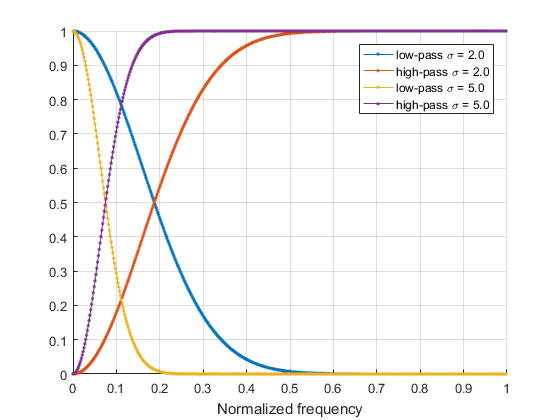

I1 = imread('./data/cheetah.jpg');
I2 = imread('./data/tiger.jpg');
I1 = im2gray(I1);
I2 = im2gray(I2);
sigma1 = 2;
sigma2 = 5;
G1d1 = gauss1d(sigma1);
G1d2 = gauss1d(sigma2);
[h1,w1] = freqz(G1d1);
[h2,w2] = freqz(G1d2);
figure
hold on
plot(w1/pi,abs(h1),'.-')
plot(w1/pi,1-abs(h1),'.-')
plot(w1/pi,abs(h2),'.-')
plot(w1/pi,1-abs(h2),'.-')
grid on
xlabel('Normalized frequency')
legend(sprintf('low-pass \\sigma = %0.1f',sigma1),sprintf('high-pass \\sigma = %0.1f',sigma1),sprintf('low-pass \\sigma = %0.1f',sigma2),sprintf('high-pass \\sigma = %0.1f',sigma2))

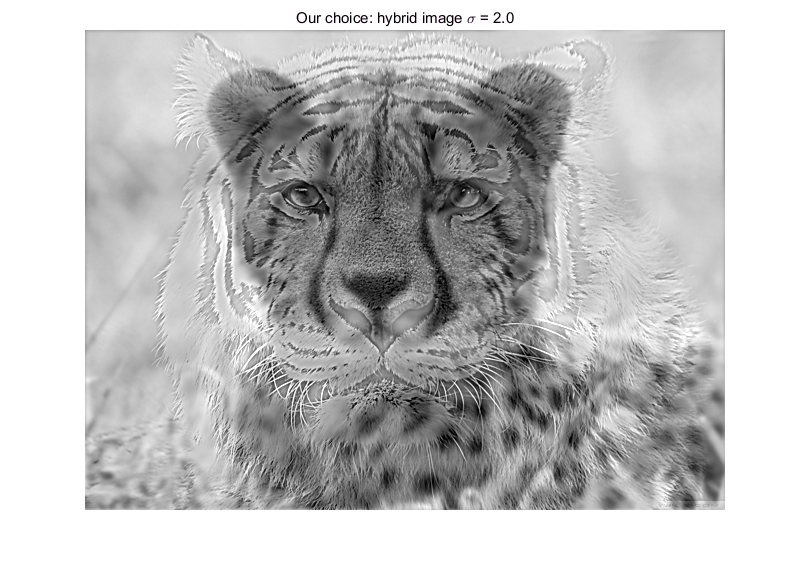


I1 = imresize(I1,[480 640]);
I2 = imresize(I2,[480 640]);
sigma1 = 2;
sigma2 = 5;
G2d1 = gauss2d(sigma1);
G2d2 = gauss2d(sigma2);
I_hybrid1 = conv2(I1,G2d1,'same')+(I2-conv2(I2,G2d1,'same'));
I_hybrid2 = conv2(I1,G2d2,'same')+(I2-conv2(I2,G2d2,'same'));
figure
imshow(I_hybrid1)
title(sprintf('Our choice: hybrid image \\sigma = %0.1f',sigma1))

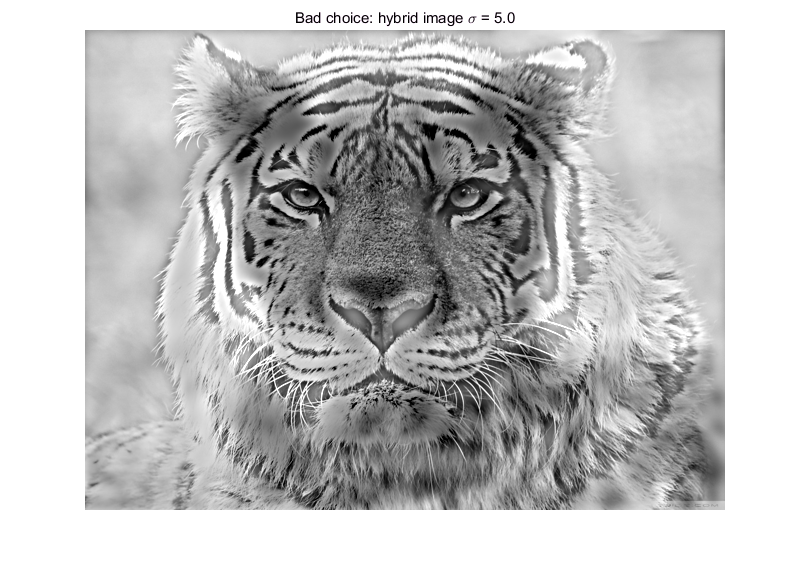

figure
imshow(I_hybrid2)
title(sprintf('Bad choice: hybrid image \\sigma = %0.1f',sigma2))

We use two images in our experiment, one for cheetah($I_1$) and one for tiger($I_2$). We apply a low-pass filter to $I_1$ and its complement, a high-pass filter to $I_2$. Follow the suggestion from the paper, we use gaussian filter as our low-pass filter. We first resize both image to a fixed dimension. Then we experiment with different $\sigma$values. As shown from the 1d frequence response of the gaussian filter, as $\sigma$increases, the cut-off frequence decreases since $f_c = \frac{1}{2\pi\sigma}$. As $\sigma$increases, we attenuate more high frequency component of $I_1$ and thus the image of cheetah can become unidentifiable even we are close to the image. For larger $\sigma$,  we also retain more high frequency componenet of $I_2$, and thus the image of tiger cannot be totally assimilated by the image of cheetah when we are 1 or 2 meters away from the image. The argument follows reversly if $\sigma$ is too small. Eventually, we choose $\sigma = 2$ and the result is much better than $\sigma = 5$ as shown.

function out=gauss1d(sigma)
w=2*floor(ceil(7*sigma)/2)+1;
xx=-(w-1)/2:(w-1)/2;
out=(1/(sqrt(2*pi)*sigma)).*exp(-(xx.^2)/(2*sigma^2));
end
function out=gauss2d(sigma)
w=2*floor(ceil(7*sigma)/2)+1;
[xx,yy]=meshgrid(-(w-1)/2:(w-1)/2,-(w-1)/2:(w-1)/2);
out=(1/(2*pi*sigma^2)).*exp(-(xx.^2+yy.^2)/(2*sigma^2));
end
function out=im2gray(im)
if size(im,3)>1
	out=im2double(rgb2gray(im));
else
	out=im2double(im);
end
end